data = readtable('../../data/data1/logvRNA.csv');

patients = unique(data.patient,'stable');
patients

patients = 6×1 cell array
    {'CHID46'}
    {'CHID77'}
    {'CHID79'}
    {'CHID32'}
    {'CHID40'}
    {'CHID08'}



num_pat = size(patients,1);


% xx0 = [0.409*10^-6 0.233*10^-6 0.249 0.775 14.5*10^3 0.03 7];
xx1 = [0.409*10^-6, 0.233*10^-6, 0.249, 0.775, 14.5*10^3, 0.03, 7];
xx2 = [0.431*10^-6, 0.140*10^-6, 0.077, 0.420, 10*10^3, 0.021, 24];
xx3 = [0.201*10^-6, 0.001*10^-6, 0.013, 1.048, 30.172*10^3, 0.036, 10];
xx4 = [9.203E-6, 0.011E-6, 0.013, 0.851, 0.548E3, 0.055, 12];
xx5 = [0.485E-6, 0.291E-6, 0.096, 0.803, 11.425E3, 0.033, 5];
xx6 = [0.057E-6, 0.004E-6, 0.021, 0.821, 89.892E3, 0.003, 22];


xx = [xx1;xx2;xx3;xx4;xx5;xx6];

h = 0.01;
init = [10^4 0 10^-3];


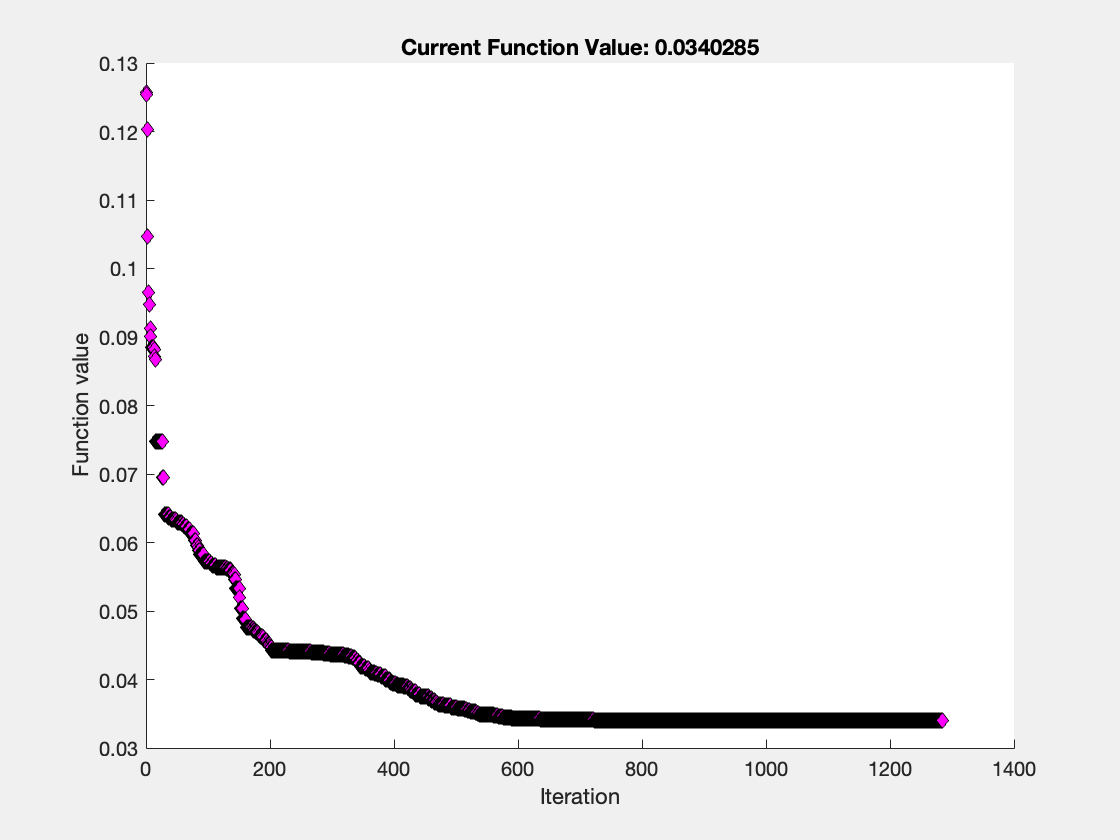


out = zeros(num_pat,8);
out2 = zeros(num_pat,8);

tic

for i = 1:num_pat
    p = string(patients(i));
    sub_data = data(data.patient == p,:);

    dpi = sub_data.dpi;
    y = sub_data.log_vRNA;

    x0 = xx(i,:);
    
    ti = 0:h:dpi(end);

    [bp, fval] = best_param(x0,dpi,y,ti,init,h);
    out(i,1) = fval;
    out(i,2:end) = bp;


    out2(i,1) = J(x0, ti,init,h, dpi,y);
    out2(i,2:end) = x0;
end 


toc

Elapsed time is 456.024661 seconds.


tb = array2table(out,'VariableNames', ...
            {'J','b0','bi','k','dlt','p','d','tau'}, ...
            'RowNames', patients)

tb = 6×8 table
                  J            b0            bi           k          dlt          p            d          tau  
              _________    __________    __________    ________    _______    __________    ________    _______

    CHID46    0.0046469    3.4497e-07    1.5821e-07       1.486     1.2266         29104    0.036181     3.8412
    CHID77     0.022019    6.2955e-07    1.7634e-07    0.042013    0.40283        7235.9    0.019252      5.705
    CHID79     0.058047    1.9796e-07     1.114e-09     0.01312      1.006         30559    0.035154      9.216
    CHID32      0.07341    1.8055e-05    1.6488e-08    0.021517    0.59473        29


writetable(tb, 'fminsearch.csv');


tb_k = array2table(out(:,4),'VariableNames',{'k'},...
                    'RowNames', patients)

tb_k = 6×1 table
                 k    
              ________

    CHID46       1.486
    CHID77    0.042013
    CHID79     0.01312
    CHID32    0.021517
    CHID40     0.17016
    CHID08    0.035013



writetable(tb_k, 'k.csv');



paper_tb = array2table(out2,'VariableNames', ...
            {'J','b0','bi','k','dlt','p','d','tau'}, ...
            'RowNames', patients)

paper_tb = 6×8 table
                 J           b0           bi         k       dlt       p        d      tau
              ________    _________    ________    _____    _____    _____    _____    ___

    CHID46    0.007939     4.09e-07    2.33e-07    0.249    0.775    14500     0.03     7 
    CHID77    0.034145     4.31e-07     1.4e-07    0.077     0.42    10000    0.021    24 
    CHID79    0.069409     2.01e-07       1e-09    0.013    1.048    30172    0.036    10 
    CHID32     0.13286    9.203e-06     1.1e-08    0.013    0.851      548    0.055    12 
    CHID40    0.021583     4.85e-07    2.91e-07    0.096    0.803    11425 


writetable(paper_tb, 'paper.csv');


%decay function 

function out=b(t,b0,bi,k,tau)
    if t <= tau
        out = b0;
    else
        out = bi+(b0-bi)*exp(-k*(t-tau));
    end
end

% predict V
function out = pred(ti,init,params)

    b0 = params(1);
    bi = params(2);
    k = params(3);
    dlt = params(4);
    p = params(5);
    d = params(6);
    tau = params(7);


    f = @(t,x) [d*(init(1)-x(1))-b(t,b0,bi,k,tau)*x(1)*x(3);...
            b(t,b0,bi,k,tau)*x(1)*x(3)-dlt*x(2);...
            p*x(2)-23*x(3) ];    

    [t,xa] = ode45(f,ti,init);
    out = xa(:,3);
 
end

%% least-sqaured error
function out=J(params, ti,init,h, dpi,y)

    V = pred(ti,init,params);
    y_hat = log10(V(dpi/h+1));
    out =  1/size(y,1) *sum((y-y_hat).^2);
end 

%% optimize J by fminsearch
function [x,fval]=best_param(x0,dpi,y,ti,init,h)
    options = optimset('PlotFcns','optimplotfval','TolFun',1e-7,'TolX',1e-7,'MaxFunEvals', 5000,'MaxIter', 5000);
    JJ = @(params) J(params, ti,init,h, dpi,y); 
    [x,fval] = fminsearch(JJ,x0,options);
end